Геренация кубической функции

y = [1:100]';
y = y .^ 3;

y_real = y;

Подготовка параметров

n_previous_days = 10;
[y, mx_y] = featureNormalizeZeroOne(y_real);
[X,y] = timeSeriesFeatures(y,n_previous_days);


s

options = optimset('MaxIter', 1000 );
lambda = 0;     %2
input_layer_size = 10;  %20
hidden_layer_size = 20; %20
num_labels = 1;

initial_Theta1 = randInitializeWeights(input_layer_size, hidden_layer_size);
initial_Theta2 = randInitializeWeights(hidden_layer_size, num_labels);
% Unroll parameters
initial_nn_params = [initial_Theta1(:) ; initial_Theta2(:)];

costFunction = @(p) nnCostFunction(p, input_layer_size, ...
    hidden_layer_size, num_labels, X, y, lambda);
[nn_params, ~] = fmincg(costFunction, initial_nn_params, options);

Iteration     1 | Cost: 8.559764e-02
Iteration     2 | Cost: 8.545655e-02
Iteration     3 | Cost: 8.401979e-02
Iteration     4 | Cost: 8.301462e-02
Iteration     5 | Cost: 7.501746e-02
Iteration     6 | Cost: 6.295232e-03
Iteration     8 | Cost: 3.420992e-03
Iteration     9 | Cost: 3.167601e-03
Iteration    10 | Cost: 3.093492e-03
Iteration    11 | Cost: 2.831668e-03
Iteration    12 | Cost: 2.662449e-03
Iteration    13 | Cost: 2.573790e-03
Iteration    14 | Cost: 2.002695e-03
Iteration    15 | Cost: 1.941073e-03
Iteration    17 | Cost: 1.913958e-03
Iteration    18 | Cost: 1.910574e-03


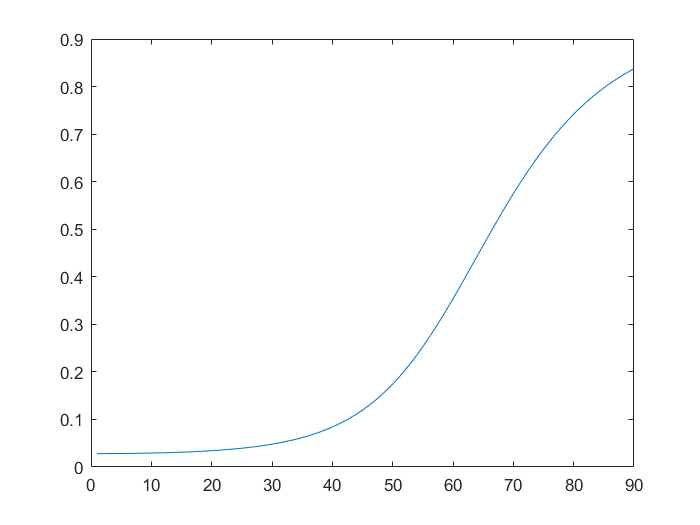

    
Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), ...
                 hidden_layer_size, (input_layer_size + 1));

Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), ...
                 num_labels, (hidden_layer_size + 1));
             
h1 = sigmoid([ones(size(X,1), 1) X] * Theta1');
hyp_train = sigmoid([ones(size(h1,1),1) h1] * Theta2');


plot(hyp_train)